vid=VideoReader("PulsVid.mp4");
fil = load("PulsData.txt");

R=transpose(fil(:,1));
G=transpose(fil(:,2));
B=transpose(fil(:,3));
R=R-mean(R);
G=G-mean(G);
B=B-mean(B);

fps=vid.FrameRate;
N=length(R);
t=0:1/fps:(N-1)/fps;

R=highpass(R,35/60,fps);


h=transpose(hann(N));
N_fft=2^(14);
df=fps/N_fft

df = 6.1035e-04

f=(-fps/2:df:fps/2-df)*60;
R_fft=fftshift(fft(h.*R,N_fft));

[r_RR,lag] = xcorr(R,R);
f_puls=max(findpeaks(r_RR))/60;

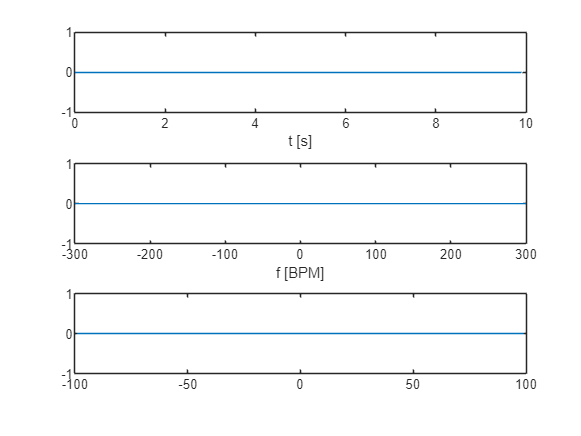

figure;

subplot(3,1,1);
plot(t,R);
xlabel("t [s]");

subplot(3,1,2);
plot(f,abs(R_fft));
xlabel("f [BPM]");

subplot(3,1,3);
plot(lag,r_RR);